# Improved gradient algorithm

## Linear regression - basic gradient descent

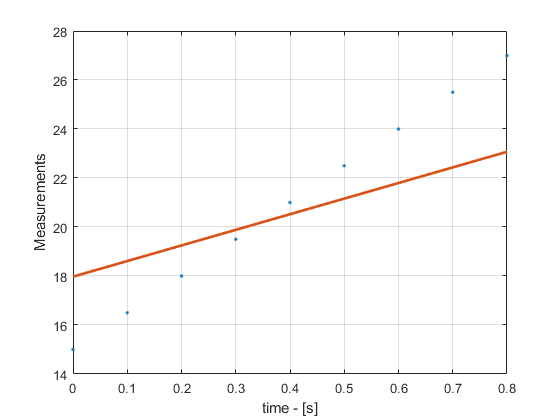

N = 18;
Te = 0.1;
a = 15;
b = 15;
t = 0:Te:(Te*N - 1);
y = a*t + b;
%y = y + normrnd(0, 5, [1 length(t)]);
stepUpperThreshold = 1000;
stepBottomTreshold = 0.0001;
beta = 1.5;

figure, 
plot(t, y, '.'); grid;
xlabel('time - [s]'); ylabel('Measurements');

evalGradient = @(theta, phi, y)(-2*sum(phi.*((y - theta*phi)), 2));
evalCost = @(theta, phi, y)(sum((y - theta*phi).^2));

step = 0.1;
theta = zeros([2, length(t)]);
phi = [t; ones([1, length(t)])];

for i = 1:(length(t)-1)
    gradient = evalGradient(theta(:, i)', phi(:, 1:i), y(1:i));
    gradient = gradient/sqrt(gradient(1)^2 + gradient(2)^2);

    theta(:, i + 1) = theta(:, i) - step.*gradient;
    cost = evalCost(theta(:, i+1)', phi(:, 1:i+1), y(1:i+1));
    newStep = step*beta;
    theta(:, i + 1) = theta(:, i) - newStep.*gradient;
    newCost = evalCost(theta(:, i+1)', phi(:, 1:i+1), y(1:i+1));
    
    if newCost < cost
        while newCost < cost && newStep < stepUpperThreshold
            newStep = newStep*beta;
            theta(:, i + 1) = theta(:, i) - newStep.*gradient;
            cost = newCost;
            newCost = evalCost(theta(:, i+1)', phi(:, 1:i+1), y(1:i+1));
        end
    else
        newStep = step/beta;
        theta(:, i + 1) = theta(:, i) - newStep.*gradient;
        newCost = evalCost(theta(:, i+1)', phi(:, 1:i+1), y(1:i+1));  
        if newCost < cost
            while newCost < cost && newStep > stepBottomTreshold
                newStep = newStep/beta;
                theta(:, i + 1) = theta(:, i) - newStep.*gradient;
                cost = newCost;
                newCost = evalCost(theta(:, i+1)', phi(:, 1:i+1), y(1:i+1));
            end
        else
            newStep = step;
        end
    end 
    theta(:, i + 1) = theta(:, i) - newStep.*gradient;
end

y_hat = theta(1, end)*t + theta(2, end);
hold on;
plot(t, y_hat, 'LineWidth', 2);

theta(:, end)

ans =     6.3714
   17.9728


## Linear Regression with Newton Steps

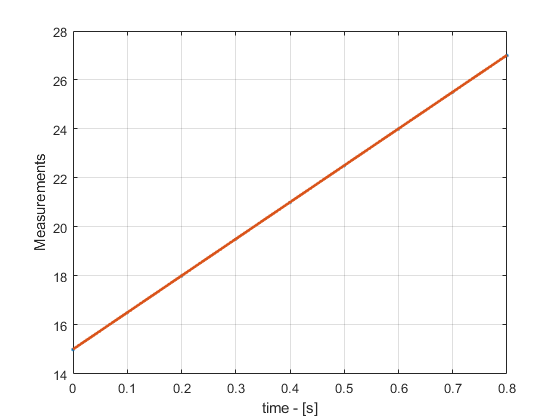

stepUpperThreshold = 1000;
stepBottomTreshold = 0.0001;
beta = 1.5;

evalGradient = @(theta, phi, y)(-2*sum(phi.*((y - theta*phi)), 2));
evalHessian = @(y, t)([2*sum(t.^2) 2*sum(t); 2*sum(t) 2*length(t)]);
evalCost = @(theta, phi, y)(sum((y - theta*phi).^2));

figure, 
plot(t, y, '.'); grid;
xlabel('time - [s]'); ylabel('Measurements');

step = 0.1;
theta = zeros([2, length(t)]);
phi = [t; ones([1, length(t)])];

for i = 2:(length(t)-1)
    gradient = evalGradient(theta(:, i)', phi(:, 1:i), y(1:i));
    gradient = gradient/sqrt(gradient(1)^2 + gradient(2)^2);
    hessian = evalHessian(y(1:i), t(1:i));
    hessian = inv(hessian)*norm(hessian);

    theta(:, i + 1) = theta(:, i) - (step.*gradient'*hessian)';
    cost = evalCost(theta(:, i+1)', phi(:, 1:i+1), y(1:i+1));
    newStep = step*beta;
    theta(:, i + 1) = theta(:, i) - (newStep.*gradient'*hessian)';
    newCost = evalCost(theta(:, i+1)', phi(:, 1:i+1), y(1:i+1));
    
    if newCost < cost
        while newCost < cost && newStep < stepUpperThreshold
            newStep = newStep*beta;
            theta(:, i + 1) = theta(:, i) - (newStep.*gradient'*hessian)';
            cost = newCost;
            newCost = evalCost(theta(:, i+1)', phi(:, 1:i+1), y(1:i+1));
        end
    else
        newStep = step/beta;
        theta(:, i + 1) = theta(:, i) - (newStep.*gradient'*hessian)';
        newCost = evalCost(theta(:, i+1)', phi(:, 1:i+1), y(1:i+1));  
        if newCost < cost
            while newCost < cost && newStep > stepBottomTreshold
                newStep = newStep/beta;
                theta(:, i + 1) = theta(:, i) - (newStep.*gradient'*hessian)';
                cost = newCost;
                newCost = evalCost(theta(:, i+1)', phi(:, 1:i+1), y(1:i+1));
            end
        else
            newStep = step;
        end
    end 
    theta(:, i + 1) = theta(:, i) - (newStep.*gradient'*hessian)';   
end

y_hat = theta(1, end)*t + theta(2, end);
hold on;
plot(t, y_hat, 'LineWidth', 2);

theta(:, end)

ans =    15.0077
   15.0077


## First order system identification using gradient descent and backtracking step finding

backTrackingStep = true;

a = 10;
b = 2;
H = tf(a, [1 b]);
Te = 0.1;
Hd = c2d(H, Te, 'zoh')

Hd =
 
    0.9063
  ----------
  z - 0.8187
 
Sample time: 0.1 seconds
Discrete-time transfer function.



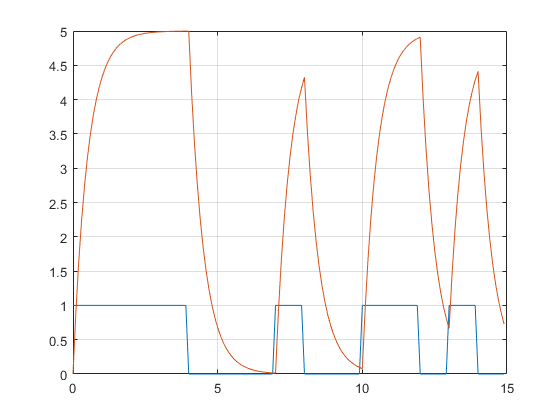


[u, t] = SPAB_GEN(4, 3, 4, Te, 10, 1);
[num, den] = tfdata(Hd, 'v');
y = dlsim(num, den, u);


figure, 
plot(t, [u' y]); grid;


evalGradient = @(theta, phi, y)(-2*sum((y - theta*phi).*(eye(2)*phi), 2));
stepUpperThreshold = 10000;
stepBottomTreshold = 0.00001;
beta = 1.2;

theta = zeros(2, length(t));
phi = [u; -y'];
step = 0.1;

tic
for i = 2:(length(t) - 1)
    gradient = evalGradient(theta(:, i)', phi(:, 1:i - 1), y(2:i)');
    gradient = gradient/sqrt(gradient(1)^2 + gradient(2)^2);
    
    if backTrackingStep == true
        theta(:, i + 1) = theta(:, i) - step.*gradient;
        cost = evalCost(theta(:, i+1)', phi(:, 1:i), y(2:i + 1)');
        newStep = step*beta;
        theta(:, i + 1) = theta(:, i) - newStep.*gradient;
        newCost = evalCost(theta(:, i+1)', phi(:, 1:i), y(2:i + 1)');
        
        if newCost < cost
            while newCost < cost && newStep < stepUpperThreshold
                newStep = newStep*beta;
                theta(:, i + 1) = theta(:, i) - newStep.*gradient;
                cost = newCost;
                newCost = evalCost(theta(:, i+1)', phi(:, 1:i), y(2:i + 1)');
            end
        else
            newStep = step/beta;
            theta(:, i + 1) = theta(:, i) - newStep.*gradient;
            newCost = evalCost(theta(:, i+1)', phi(:, 1:i), y(2:i + 1)'); 
            if newCost < cost
                while newCost < cost && newStep > stepBottomTreshold
                    newStep = newStep/beta;
                    theta(:, i + 1) = theta(:, i) - newStep.*gradient;
                    cost = newCost;
                    newCost = evalCost(theta(:, i+1)', phi(:, 1:i), y(2:i + 1)');
                end
            else
                newStep = step;
            end
        end 
        theta(:, i + 1) = theta(:, i) - newStep.*gradient;
    else
        theta(:, i + 1) = theta(:, i) - step.*gradient;
    end
end
toc

Elapsed time is 0.049403 seconds.


theta(:, end)

ans =     0.9062
   -0.8187


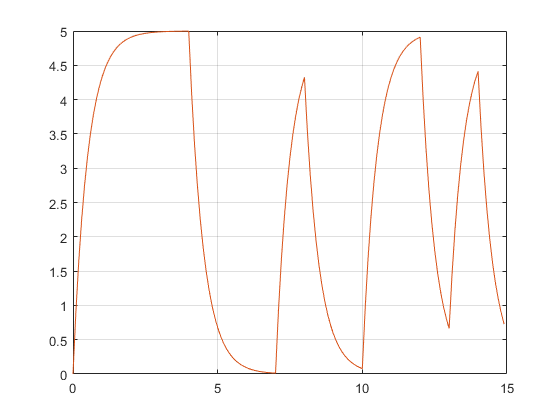

Hid = tf(theta(1, end), [1 theta(2, end)], Te);
[num, den] = tfdata(Hid, 'v');
ys = dlsim(num, den, u);

figure,
plot(t, [y ys]); grid;

## First order system identification using gradient descent and Newton steps

backTrackingStep = true;

evalGradient = @(theta, phi, y)(-2*sum((y - theta*phi).*(eye(2)*phi), 2));
evalHessian = @(phi)([2*sum(phi(1, :).^2) 2*sum(phi(1, :).*phi(2, :)); ...
                      2*sum(phi(1, :).*phi(2, :)) 2*sum(phi(2, :).^2)]);
theta = zeros(2, length(t));
phi = [u; -y'];
step = 0.01;
stepUpperThreshold = 10000;
stepBottomTreshold = 0.00001;
beta = 1.1;
tic
for i = 3:(length(t)-1)
    gradient = evalGradient(theta(:, i)', phi(:, 1:i - 1), y(2:i)');
    gradient = gradient/sqrt(gradient(1)^2 + gradient(2)^2);
    hessian = evalHessian(phi(:, 1:i - 1));
    hessian = hessian/norm(hessian);
    
    if backTrackingStep == true
        if det(hessian) == 0
            theta(:, i + 1) = theta(:, i) - step*gradient;
        else
            theta(:, i + 1) = theta(:, i) - (step*hessian\gradient);
        end
        cost = evalCost(theta(:, i+1)', phi(:, 1:i), y(2:i + 1)');
        newStep = step*beta;
        if det(hessian) == 0
            theta(:, i + 1) = theta(:, i) - newStep*gradient;
        else
            theta(:, i + 1) = theta(:, i) - (newStep*hessian\gradient);
        end
        newCost = evalCost(theta(:, i+1)', phi(:, 1:i), y(2:i + 1)');
        
        if newCost < cost
            while newCost < cost && newStep < stepUpperThreshold
                newStep = newStep*beta;
                if det(hessian) == 0
                    theta(:, i + 1) = theta(:, i) - newStep*gradient;
                else
                    theta(:, i + 1) = theta(:, i) - (newStep*hessian\gradient);
                end
                cost = newCost;
                newCost = evalCost(theta(:, i+1)', phi(:, 1:i), y(2:i + 1)');
            end
        else
            newStep = step/beta;
            if det(hessian) == 0
                theta(:, i + 1) = theta(:, i) - newStep*gradient;
            else
                theta(:, i + 1) = theta(:, i) - (newStep*hessian\gradient);
            end
            newCost = evalCost(theta(:, i+1)', phi(:, 1:i), y(2:i + 1)'); 
            if newCost < cost
                while newCost < cost && newStep > stepBottomTreshold
                    newStep = newStep/beta;
                    if det(hessian) == 0
                        theta(:, i + 1) = theta(:, i) - newStep*gradient;
                    else
                        theta(:, i + 1) = theta(:, i) - (newStep*hessian\gradient);
                    end
                    cost = newCost;
                    newCost = evalCost(theta(:, i+1)', phi(:, 1:i), y(2:i + 1)');
                end
            else
                newStep = step;
            end
        end 
        if det(hessian) == 0
            theta(:, i + 1) = theta(:, i) - newStep*gradient;
        else
            theta(:, i + 1) = theta(:, i) - (newStep*hessian\gradient);
        end
    else
        if det(hessian) == 0
            theta(:, i + 1) = theta(:, i) - step*gradient; 
        else
            theta(:, i + 1) = theta(:, i) - (step*hessian\gradient);
        end
    end
end
toc

Elapsed time is 0.181850 seconds.


theta(:, end)

ans =     0.9063
   -0.8187


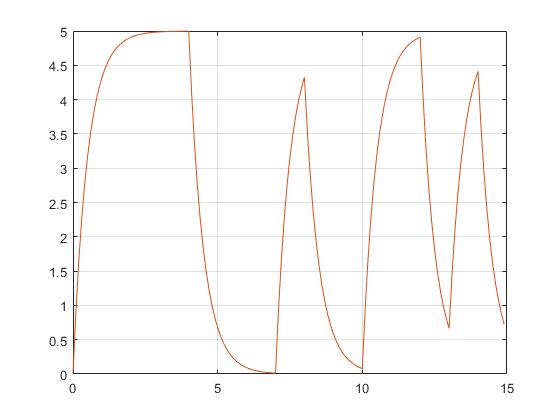

Hid = tf(theta(1, end), [1 theta(2, end)], Te);
[num, den] = tfdata(Hid, 'v');
ys = dlsim(num, den, u);

figure,
plot(t, [y ys]); grid;

function [spab, t] = SPAB_GEN(N, i, j, Te, alpha, numberOfPeriods)
    register = ones(1, N*numberOfPeriods);
    spab = zeros(1, (2^N - 1)*alpha*numberOfPeriods);
    t = 0:Te:((2^N - 1)*alpha*Te)*numberOfPeriods - Te;
    m = 1;
    
    for k = 1:(2^N - 1)*numberOfPeriods
        spab(m:m + alpha - 1) = register(end)*ones(1, alpha);
        m = m + alpha;
        aux = xor(register(i), register(j));
        register = [aux register(1:N - 1)];
    end
end